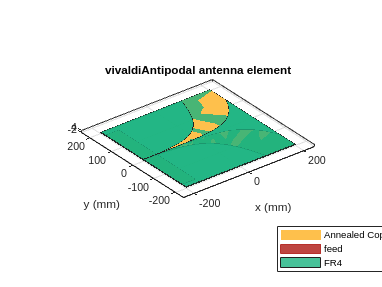

l = 0.4;
w = 0.4;
opening_rate = 18;
sma_connector_pin_diameter = 1.8e-3;
inner_taper_length = 0.35;
outer_taper_length = inner_taper_length * 0.70;
working_outer_taper_length = 0.18;
copper_thickness = 4.064e-4;
PCB_thickness = 1.524e-3;
apature_width = 0.25;
m = metal(Name = 'Annealed Copper', Conductivity=5.8001e07, Thickness = copper_thickness);
avi=vivaldiAntipodal( ...
    'BoardLength',l, ...
    'BoardWidth', w, ...
    'Height',PCB_thickness,...
    'OpeningRate',opening_rate, ...
    'GroundPlaneWidth',w*0.9,...
    'ApertureWidth',apature_width,...
    'StripLineWidth', sma_connector_pin_diameter,...
    'InnerTaperLength',inner_taper_length,...
    'OuterTaperLength',outer_taper_length,...
    'Conductor', m,...
    'Substrate',dielectric('Name','FR4','EpsilonR',4.8,'LossTangent',0.026,'Thickness',PCB_thickness));
show(avi);

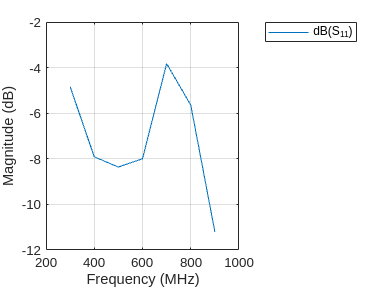


S = sparameters(avi,lowest_freq - offset:1e8:highest_freq + offset);
rfplot(S);

impedance(avi,lowest_freq - offset:1e8:highest_freq + offset);


lowest_freq = 300e6;
highest_freq = 900e6;
offset = 50;
pattern(avi, lowest_freq);
patternAzimuth(avi, lowest_freq);
patternElevation(avi, lowest_freq);

for i = 1:3
    possible_offsets = i*-0.05;
    ava=vivaldiAntipodal( ...
        'BoardLength',l, ...
        'BoardWidth', w, ...
        'Height',PCB_thickness,...
        'OpeningRate',opening_rate, ...
        'GroundPlaneWidth',w*0.9,...
        'ApertureWidth',apature_width,...
        'StripLineWidth', sma_connector_pin_diameter,...
        'InnerTaperLength',inner_taper_length,...
        'OuterTaperLength',outer_taper_length + possible_offsets,...
        'Conductor', m,...
        'Substrate',dielectric('Name','FR4','EpsilonR',4.8,'LossTangent',0.026,'Thickness',PCB_thickness));
    fprintf('Plot %d', i);
    rfplot(sparameters(ava,lowest_freq - offset:1e8:highest_freq + offset));
end